clear; clc;

%% =================================================================
%% 1. CAMERA PERCEPTION & HOMOGENEOUS TRANSFORMS
%% =================================================================
% Initialize pipeline and config
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable streams (Note: Changed bgr8 to rgb8 for easier MATLAB color processing)
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

% Initialize pointcloud object
pc = realsense.pointcloud();

% Create align object to ensure depth perfectly matches color pixels
align_to_color = realsense.align(realsense.stream.color);

% Start pipeline
profile = pipe.start(cfg);

disp('Warming up camera...');

Warming up camera...


i = 0;
while i < 5
    % Wait for frames
    fs = pipe.wait_for_frames();
    
    % Align frames so depth and color pixels correspond 1:1
    fs = align_to_color.process(fs);
    
    % Get depth frame
    depth_frame = fs.get_depth_frame();
    
    % Get color frame
    color_frame = fs.get_color_frame();
    
    i = i + 1;
    
    % Map pointcloud to color and calculate points
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    
    % Get vertices natively
    vtx = points.get_vertices();
end

% Stop streaming
pipe.stop();
disp('Camera stopped. Processing final frame...');

Camera stopped. Processing final frame...



% --- Extract RGB Image ---
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);

% --- Transformation Matrix ---
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065
   -0.9999    0.0103    0.0047    0.0586
   -0.0043    0.0408   -0.9992    0.705
         0         0         0    1.0000];

valid_depth = (vtx(:,3) > 0); 

%% =================================================================
%% 2. ARUCO MARKER DETECTION (DESTINATION TRAYS)
%% =================================================================
disp('Detecting ArUco Markers for Destination Trays (ID 0 = Blue, ID 2 = Green)...');

Detecting ArUco Markers for Destination Trays (ID 0 = Blue, ID 2 = Green)...


[markerIds, markerLocs] = readArucoMarker(I);

blue_bin_found = false;
green_bin_found = false;

if ~isempty(markerIds)
    for i = 1:length(markerIds)
        current_id = markerIds(i);
        corners = markerLocs(:,:,i);
        
        % Create a 2D binary mask from the ArUco corners
        mask_2d = poly2mask(corners(:,1), corners(:,2), 480, 640);
        mask_1d = reshape(mask_2d', [], 1);
        
        bin_vtx = vtx(valid_depth & mask_1d, :);
        
        if ~isempty(bin_vtx)
            bin_pos_cam = mean(bin_vtx, 1);
            bin_pos_world_homog = T_world_camera * [bin_pos_cam, 1]';
            
            % Assign to respective tray based on ID
            if current_id == 0
                blue_place_x = bin_pos_world_homog(1) * 1000;
                blue_place_y = bin_pos_world_homog(2) * 1000;
                blue_bin_found = true;
                
                blue_pixel_x = mean(corners(:,1));
                blue_pixel_y = mean(corners(:,2));
                fprintf('Blue Tray (ID 0) Detected at World X: %.1f mm, Y: %.1f mm\n', blue_place_x, blue_place_y);
            elseif current_id == 2
                green_place_x = bin_pos_world_homog(1) * 1000;
                green_place_y = bin_pos_world_homog(2) * 1000;
                green_bin_found = true;
                
                green_pixel_x = mean(corners(:,1));
                green_pixel_y = mean(corners(:,2));
                fprintf('Green Tray (ID 2) Detected at World X: %.1f mm, Y: %.1f mm\n', green_place_x, green_place_y);
            end
        end
    end
else
    disp('No ArUco markers found in the scene!');
end

Blue Tray (ID 0) Detected at World X: -178.6 mm, Y: -4.7 mm



%% =================================================================
%% 3. DETECT BLUE CUBE & CALCULATE PLACEMENT
%% =================================================================
disp('Detecting Blue Cube Target...');

Detecting Blue Cube Target...



% --- 2D HSV Color Segmentation (BLUE) ---
hsvI = rgb2hsv(I);
H = hsvI(:,:,1); 
S = hsvI(:,:,2); 
V = hsvI(:,:,3);

% STRICTER COLOR THRESHOLDS
hueMask = (H > 0.52) & (H < 0.65); 
level = max(graythresh(S), 0.40); 
mask = hueMask & (S > level) & (V > 0.25); 

% Clean up the mask
mask = bwareaopen(mask, 100); 
mask = imfill(mask, 'holes');

% GEOMETRIC FILTERING
stats = regionprops(mask, 'Area', 'PixelIdxList', 'Solidity', 'Centroid');
robust_mask = false(size(mask));

for j = 1:length(stats)
    if stats(j).Area > 300 && stats(j).Area < 15000 && stats(j).Solidity > 0.80
        robust_mask(stats(j).PixelIdxList) = true;
    end
end
mask = robust_mask;

% --- Filter the Point Cloud ---
mask_1d = reshape(mask', [], 1);
blue_indices = valid_depth & mask_1d;
blue_vtx = vtx(blue_indices, :);

if isempty(blue_vtx)
    disp('No blue objects found in the 3D space! Aborting sequence.');
    return;
end

ptCloud = pointCloud(blue_vtx);
[labels, numClusters] = pcsegdist(ptCloud, 0.008);

if numClusters == 0
    disp('Could not find a distinct physical object. Aborting sequence.');
    return;
end

% Find the largest dense cluster
clusterSizes = zeros(numClusters, 1);
for c = 1:numClusters
    clusterSizes(c) = sum(labels == c);
end
[~, biggestClusterIdx] = max(clusterSizes);

cubeIndices = find(labels == biggestClusterIdx);
cubeCloud = select(ptCloud, cubeIndices);

% Calculate the centroid of ONLY the clustered cube
pos_cam = mean(cubeCloud.Location, 1);
pos_world_homog = T_world_camera * [pos_cam(1); pos_cam(2); pos_cam(3); 1];
curr_pos_world = pos_world_homog(1:3)';

%% =================================================================
%% 3.5 SWEEPING RECTANGLE ORIENTATION LOGIC
%% =================================================================
jaw_tolerance_deg = 12.5; 
points_cam_homog = [cubeCloud.Location, ones(size(cubeCloud.Location, 1), 1)]'; 
points_world = (T_world_camera * points_cam_homog)'; 

max_z = max(points_world(:, 3)); 
top_face_indices = points_world(:, 3) > (max_z - 0.005);
top_points_xy = points_world(top_face_indices, 1:2); 

% 1. Sweep angles from 0 to 89 to find the tightest bounding box
search_angles = 0:1:89;
areas = zeros(size(search_angles));
box_widths = zeros(size(search_angles));
box_heights = zeros(size(search_angles));

for a_idx = 1:length(search_angles)
    t = deg2rad(search_angles(a_idx));
    % Unit vectors along and perpendicular to the search angle
    u = [cos(t); sin(t)];
    v = [-sin(t); cos(t)];
    
    % Project points onto the vectors
    proj_u = top_points_xy * u;
    proj_v = top_points_xy * v;
    
    % Calculate width and height of the box at this rotation
    w = max(proj_u) - min(proj_u);
    h = max(proj_v) - min(proj_v);
    
    areas(a_idx) = w * h;
    box_widths(a_idx) = w;
    box_heights(a_idx) = h;
end

% 2. Get the angle that minimizes the bounding box area
[~, min_idx] = min(areas);
best_angle_deg = search_angles(min_idx);
final_w = box_widths(min_idx);
final_h = box_heights(min_idx);

% 3. Determine shape & exact angle
aspect_ratio = max(final_w, final_h) / min(final_w, final_h);
is_rect = false;
curr_angle_deg = best_angle_deg;

if aspect_ratio > 1.3 
    is_rect = true;
    % For rectangles, we must align with the longer side
    if final_h > final_w
        curr_angle_deg = mod(best_angle_deg + 90, 180);
    end
end

% =========================================================
% Feasibility Math (Cleaned up wrapping)
% =========================================================
theta_arm_deg = rad2deg(atan2(curr_pos_world(2), curr_pos_world(1)));
angular_diff = curr_angle_deg - theta_arm_deg;

if is_rect
    % Rectangles are only symmetric every 180 degrees.
    % The arm must align with the long axis to squeeze the short sides.
    curr_angular_error = abs(mod(angular_diff + 90, 180) - 90);
else
    % Squares are symmetric every 90 degrees.
    curr_angular_error = abs(mod(angular_diff + 45, 90) - 45);
end

is_feasible = (curr_angular_error <= jaw_tolerance_deg);

% Calculate Pixel Centroid for Visualization
[py, px] = find(labels == biggestClusterIdx); % rough fallback
if ~isempty(stats)
    pixel_x_target = stats(1).Centroid(1);
    pixel_y_target = stats(1).Centroid(2);
else
    pixel_x_target = mean(px);
    pixel_y_target = mean(py);
end

% Initialize Targets Array
all_targets = struct('id', {}, 'color', {}, 'pos', {}, 'angle', {}, 'error', {}, 'feasible', {}, 'is_rect', {}, 'pixel_x', {}, 'pixel_y', {});
target_idx = 1;
all_targets(target_idx).id = target_idx;
all_targets(target_idx).color = 'Blue';
all_targets(target_idx).pos = curr_pos_world;
all_targets(target_idx).angle = curr_angle_deg;
all_targets(target_idx).error = curr_angular_error;
all_targets(target_idx).feasible = (curr_angular_error <= jaw_tolerance_deg);
all_targets(target_idx).is_rect = is_rect;
all_targets(target_idx).pixel_x = pixel_x_target;
all_targets(target_idx).pixel_y = pixel_y_target;

%% =================================================================
%% 4. DEBUGGING / VERIFICATION TABLE & VISUALIZATION
%% =================================================================
fprintf('\n===========================================================================\n');

fprintf(' DETECTED OBJECTS REPORT \n');

 DETECTED OBJECTS REPORT 


fprintf('===========================================================================\n');

fprintf('%-5s | %-7s | %-6s | %-6s | %-6s | %-7s | %-6s | %-10s\n', ...
    'ID', 'Color', 'X(mm)', 'Y(mm)', 'Z(mm)', 'Angle', 'IsRect', 'Feasible');

ID    | Color   | X(mm)  | Y(mm)  | Z(mm)  | Angle   | IsRect | Feasible  


fprintf('---------------------------------------------------------------------------\n');

---------------------------------------------------------------------------



for i = 1:length(all_targets)
    t = all_targets(i);
    feasible_str = 'YES'; if ~t.feasible, feasible_str = 'NO'; end
    rect_str = 'NO'; if t.is_rect, rect_str = 'YES'; end
    fprintf('%-5d | %-7s | %-6.1f | %-6.1f | %-6.1f | %-7.1f | %-6s | %-10s\n', ...
        t.id, t.color, t.pos(1)*1000, t.pos(2)*1000, t.pos(3)*1000, t.angle, rect_str, feasible_str);
end

1     | Blue    | 172.9  | -3.4   | 20.5   | 0.0     | YES    | YES       


fprintf('===========================================================================\n\n');


% Create the figure window explicitly
f = figure('Name', 'Workspace Target Debug', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);
imshow(I); 
hold on;

% --- Draw Both ArUco Trays ---
if blue_bin_found
    plot(blue_pixel_x, blue_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'b');
    text(blue_pixel_x + 20, blue_pixel_y, 'BLUE TRAY (ID 0)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
end

if green_bin_found
    plot(green_pixel_x, green_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'g');
    text(green_pixel_x + 20, green_pixel_y, 'GREEN TRAY (ID 2)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
end

for i = 1:length(all_targets)
    t = all_targets(i);
    marker_color = 'b'; if strcmp(t.color, 'Green'), marker_color = 'g'; end
    text_bg = 'k'; if ~t.feasible, text_bg = 'r'; end
    
    plot(t.pixel_x, t.pixel_y, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', marker_color);
    annot_str = sprintf('ID:%d | %d\\circ\nF:%d | R:%d', t.id, round(t.angle), t.feasible, t.is_rect);
    text(t.pixel_x + 15, t.pixel_y, annot_str, 'Color', 'w', 'BackgroundColor', text_bg, 'FontSize', 9, 'FontWeight', 'bold', 'Margin', 1);
end
hold off;

% UI Button
btn = uicontrol(f, 'Style', 'pushbutton', 'String', 'START ROBOT', 'Position', [20, 20, 150, 50], ...
    'FontSize', 12, 'FontWeight', 'bold', 'BackgroundColor', 'g', 'Callback', 'uiresume(gcbf)');

disp('Image generated. Waiting for you to click "START ROBOT" on the image window...');

Image generated. Waiting for you to click "START ROBOT" on the image window...


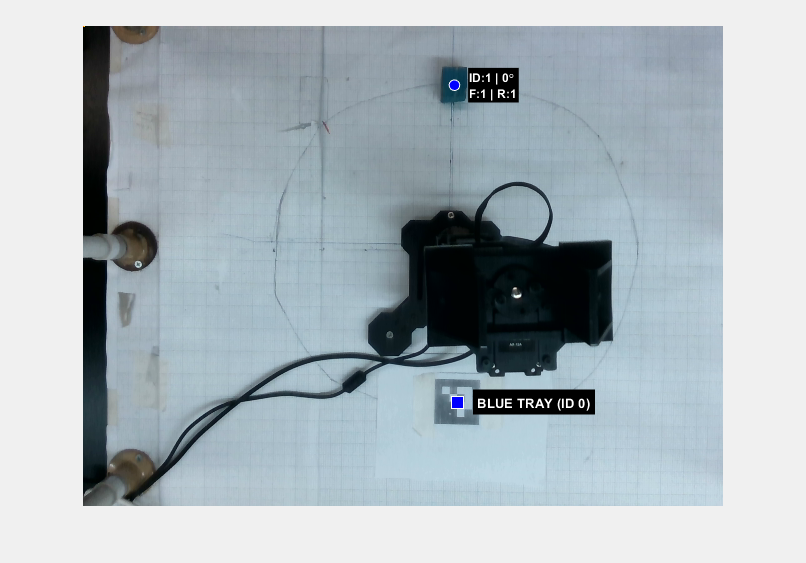

drawnow limitrate; shg; 

uiwait(f);

if isvalid(btn), delete(btn); end

disp('Button clicked! Proceeding to hardware sequence...');

Button clicked! Proceeding to hardware sequence...


drawnow; shg; 

disp('Waiting for user confirmation to proceed...');

Waiting for user confirmation to proceed...


h_msg = msgbox('Review the target map. Click OK to begin the physical sorting sequence...', 'Ready to Sort');
uiwait(h_msg); 
input('Press Enter to begin the physical sorting sequence...', 's');

% Force feasibility check before acting
if ~all_targets(1).feasible
    disp('--> RESULT: INVALID PICK! Cube orientation is unfeasible.');
    disp('Aborting sequence to prevent knocking the object away.');
    return; 
end

%% =================================================================
%% 5. DEFINE TARGET COORDINATES FOR ROBOT [X, Y, Z, Phi]
%% =================================================================
disp('Calculating Robot Waypoints...');

Calculating Robot Waypoints...



% Convert world coordinates to millimeters for the robot
pick_x = all_targets(1).pos(1) * 1000;
pick_y = all_targets(1).pos(2) * 1000;
pick_z = all_targets(1).pos(3) * 1000;

% Validate Place Target
if ~blue_bin_found
    disp('ERROR: Blue place bin (ArUco ID 0) not found. Cannot determine place coordinates. Aborting!');
    return;
end

% Setup Pick and Place Arrays
pick  = [pick_x, pick_y, pick_z, deg2rad(175)];  
place = [blue_place_x, blue_place_y, pick_z+5, deg2rad(175)]; % Placing uses ArUco X/Y, Z is table height/tray height

% Calculate pre-pick and pre-place (50mm exactly above targets)
z_offset_mm = 60;
pre_pick  = pick  + [0, 0, z_offset_mm, 0];
pre_place = place + [0, 0, z_offset_mm, 0];

% Gripper & Speed Values
jaw_open_val  = 34;
jaw_close_val = 28;
speed = 100;

%% =================================================================
%% 6. INITIALIZE ROBOT CONNECTION
%% =================================================================
port = 'COM5'; 
numServos = 5; 

try
    arb = Arbotix('port', port, 'nservos', numServos);
    fprintf('Successfully connected to Pincher on %s\n\n', port);
catch
    error('Could not connect. Ensure %s is free and the robot is powered on.', port);
end

i = 4

Successfully connected to Pincher on COM5




disp('Maximizing servo stiffness (Setting Compliance Margin to 0)...');

Maximizing servo stiffness (Setting Compliance Margin to 0)...


ADDR_CW_COMPLIANCE_MARGIN = 26;
ADDR_CCW_COMPLIANCE_MARGIN = 27;

% Loop through servos to set stiffness
arb.writedata1(1, ADDR_CW_COMPLIANCE_MARGIN, 2);
arb.writedata1(1, ADDR_CCW_COMPLIANCE_MARGIN, 2);
arb.writedata1(2, ADDR_CW_COMPLIANCE_MARGIN, 8);
arb.writedata1(2, ADDR_CCW_COMPLIANCE_MARGIN, 8);

pause(0.5); 
disp('Stiffness maximized.');

Stiffness maximized.



%% =================================================================
%% 7. EXECUTE PICK AND PLACE SEQUENCE
%% =================================================================
% A. Open Gripper & Go Home
fprintf('Opening Jaw and Homing Robot...\n');

Opening Jaw and Homing Robot...


[~, th_open] = positionJaw(jaw_open_val);
arb.setpos(5, th_open, speed);

for i = 1:4
    arb.setpos(i, 0, speed);
end
pause(3);

% B. Move to Pre-Pick, then Pick
fprintf('Moving to Pre-Pick [%.1f, %.1f, %.1f]...\n', pre_pick(1), pre_pick(2), pre_pick(3));

Moving to Pre-Pick [172.9, -3.4, 80.5]...


moveRobotToTarget(arb, pre_pick, speed, 2); 

fprintf('Moving down to Pick [%.1f, %.1f, %.1f]...\n', pick(1), pick(2), pick(3));

Moving down to Pick [172.9, -3.4, 20.5]...


moveRobotToTarget(arb, pick, speed, 2);     

% C. Close Gripper (Grab)
fprintf('Closing Jaw to grab object...\n');

Closing Jaw to grab object...


[~, th_close] = positionJaw(jaw_close_val);
arb.setpos(5, th_close, speed);
pause(2);

% E. Move to Pre-Pick, then Home
fprintf('Moving up to Pre-Pick...\n');

Moving up to Pre-Pick...


moveRobotToTarget(arb, pre_pick, speed, 2);

fprintf('Returning to Home position...\n');

Returning to Home position...


for i = 1:4
    arb.setpos(i, 0, speed);
end
pause(2);

% F. Move to Pre-Place, then Place
fprintf('Moving across to Pre-Place (Over ArUco Bin)...\n');

Moving across to Pre-Place (Over ArUco Bin)...


moveRobotToTarget(arb, pre_place, speed, 2);

fprintf('Moving down to Place...\n');

Moving down to Place...


moveRobotToTarget(arb, place, speed, 2);

% G. Open Gripper
fprintf('Opening Jaw to release object...\n');

Opening Jaw to release object...


arb.setpos(5, th_open, speed);
pause(2);

% H. Move back up to Pre-Place, then Home
fprintf('Moving up to Pre-Place...\n');

Moving up to Pre-Place...


moveRobotToTarget(arb, pre_place, speed, 2);

fprintf('Returning to Home position...\n');

Returning to Home position...


for i = 1:4
    arb.setpos(i, 0, speed);
end
pause(2); 

fprintf('Sequence Complete!\n');

Sequence Complete!



%% =================================================================
%% LOCAL HELPER FUNCTIONS
%% =================================================================
function moveRobotToTarget(arb, target, speed, pause_time)

    fullConfig = zeros(1, 4);
    for i = 1:4
        pos = arb.getpos(i);
        if ~isempty(pos)
            fullConfig(i) = pos;
        end
    end
    
    % --- THE COMBINED FRAME CALIBRATION ---
    % dx = 1.003;  
    % dy = -1.237;  
    
     dx = 7.896;  
    dy = -0.885;  
    x_shifted = target(1) + dx;
    y_shifted = target(2) + dy;
    
    angle_offset_deg =-1.104; %-1.944; 
    theta = deg2rad(angle_offset_deg);
    
    x_corrected = x_shifted * cos(theta) - y_shifted * sin(theta);
    y_corrected = x_shifted * sin(theta) + y_shifted * cos(theta);
    
    % ==========================================
    % PURE MATH DYNAMIC PHI 
    % ==========================================
    theta1_ideal_deg = rad2deg(atan2(y_corrected, x_corrected));
    
    if theta1_ideal_deg > -45 && theta1_ideal_deg <= 135
        dynamic_phi_deg = 175;    
    else
        dynamic_phi_deg = 185;
    end
    
    radius = sqrt(x_corrected^2 + y_corrected^2);
    if radius > 185
        dynamic_phi_deg = 180; 
    end
    
    dynamic_phi = deg2rad(dynamic_phi_deg);

    solutions = findSolution(x_corrected, y_corrected, target(3), dynamic_phi, fullConfig);
    
    if isempty(solutions)
        error('IK Solver failed: No valid joint angles found for this target.');
    end
    
    for joint = 1:4
        arb.setpos(joint, solutions(joint), speed);
    end
    pause(pause_time);
end